# Chap 4 - Embeddings

% Define the paragraph as a string literal using concatenation for readability
paragraph = "It was the best of times, it was the worst of times, " + ...
    "it was the age of wisdom, it was the age of foolishness, " + ...
    "it was the epoch of belief, it was the epoch of incredulity, " + ...
    "it was the season of Light, it was the season of Darkness, " + ...
    "it was the spring of hope, it was the winter of despair, " + ...
    "we had everything before us, we had nothing before us, " + ...
    "we were all going direct to Heaven, we were all going direct the other way " + ...
    "- in short, the period was so far like the present period, " + ...
    "that some of its noisiest authorities insisted on its being received, " + ...
    "for good or for evil, in the superlative degree of comparison only.";

% Split the paragraph into sentences using ", " as the delimiter
sentences = split(paragraph, ", ");

% Select the first sentence (MATLAB indexing starts at 1)
sentence1 = sentences(1)

sentence1 = "It was the best of times"

### OpenAI embedding service

emb = extractOpenAIEmbeddings(sentence1)

emb =     0.0100   -0.0019    0.0083   -0.0402   -0.0179    0.0026   -0.0008   -0.0045   -0.0127   -0.0410    0.0035    0.0257    0.0134   -0.0020    0.0047    0.0106    0.0423    0.0003   -0.0036   -0.0005   -0.0047    0.0214    0.0023   -0.0077   -0.0109    0.0012    0.0026   -0.0274    0.0306   -0.0002   -0.0005   -0.0038   -0.0222   -0.0073   -0.0333   -0.0561   -0.0322   -0.0087    0.0070    0.0050    0.0131   -0.0067   -0.0031    0.0237   -0.0276    0.0074    0.0137    0.0051   -0.0172    0.0015


size(emb)

ans =            1        1536


embs = extractOpenAIEmbeddings(sentences)

embs =     0.0100   -0.0019    0.0083   -0.0402   -0.0179    0.0026   -0.0008   -0.0045   -0.0127   -0.0410    0.0035    0.0257    0.0134   -0.0020    0.0047    0.0106    0.0423    0.0003   -0.0036   -0.0005   -0.0047    0.0214    0.0023   -0.0077   -0.0109    0.0012    0.0026   -0.0274    0.0306   -0.0002   -0.0005   -0.0038   -0.0222   -0.0073   -0.0333   -0.0561   -0.0322   -0.0087    0.0070    0.0050    0.0131   -0.0067   -0.0031    0.0237   -0.0276    0.0074    0.0137    0.0051   -0.0172    0.0015
   -0.0169    0.0028    0.0003   -0.0268   -0.0102    0.0076   -0.0040   -0.0052   -0.0151   -0.0424    0.0038    0.0312    0.0170    0.0168   -0.0017    0.0100    0.0420    0.0116    0.0040    0.0043    0.0018    0.0244   -0.0022    0.0017   -0.0106   -0.0002    0.0091   -0.0296    0.0303   -0.0143   -0.0144   -0.0099   -0.0159   -0.0165   -0.0405   -0.0398   -0.0019   -0.0112    0.0035   -0.0126    0.0120   -0.0123    0.0014    0.0238   -0.0453    0.0028   -0.0000   -0.0136   -0.0255  

### Semantic similarity

Since the norm of the vector embeddings is 1, cosine similarity between the vectors results in a simple dot product.

norm(emb)

ans = 1.0000

dot(embs(1,:),embs(2,:))

ans = 0.9032

sentences(1),sentences(2)

ans = "It was the best of times"

ans = "it was the worst of times"

### Open-source embedding model

model = py.sentence_transformers.SentenceTransformer('all-MiniLM-L6-v2'); % or 'all-mpnet-base-v2'
embedding1 = model.encode(sentence1)

embedding1 =   Python ndarray:

   -0.0452    0.0717    0.0172   -0.0317    0.0477   -0.0080    0.0122    0.0578   -0.0235    0.0005   -0.0059    0.1645    0.0872    0.0576   -0.0097    0.0257    0.0318    0.0049   -0.0225   -0.0381   -0.0568   -0.0270    0.0123    0.0493    0.0092    0.0301    0.0072    0.0636   -0.0289    0.0343   -0.0390   -0.0201    0.0009    0.0116   -0.0567    0.0033    0.0108   -0.0677    0.0246   -0.0008    0.0038   -0.0342   -0.0243   -0.0844    0.0169    0.0033    0.0806   -0.0887    0.0559    0.0244    0.0477   -0.0114    0.0462   -0.0806    0.0774    0.0492    0.0203   -0.0239    0.0524   -0.0098   -0.0552    0.0314   -0.0333    0.0791    0.0285   -0.0283   -0.0384    0.0542   -0.0150    0.1183   -0.0650    0.0174   -0.0081   -0.0539    0.0166    0.0465    0.0081   -0.0310   -0.0453    0.0762    0.0454   -0.0561   -0.0078    0.0448   -0.0041   -0.0303    0.0292   -0.0523    0.0565  

embedding1.shape

ans =   Python tuple with values:

    (384,)

    Use string, double or cell function to convert to a MATLAB array.


### Plotting embeddings

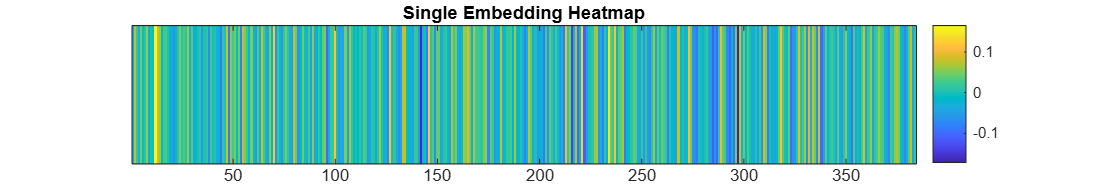

emb1 = double(embedding1);
plotSingleEmbedding(emb1)

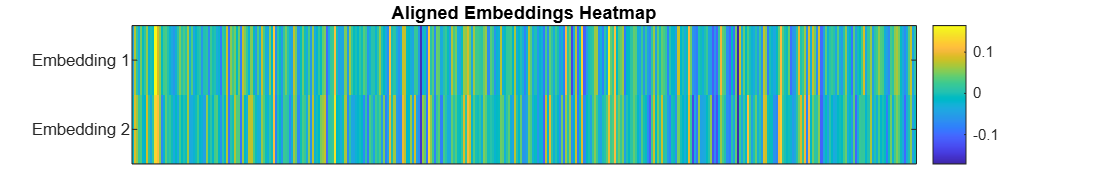

emb2 = double(model.encode(sentences(2)));
plotAlignedEmbeddings(emb1, emb2)

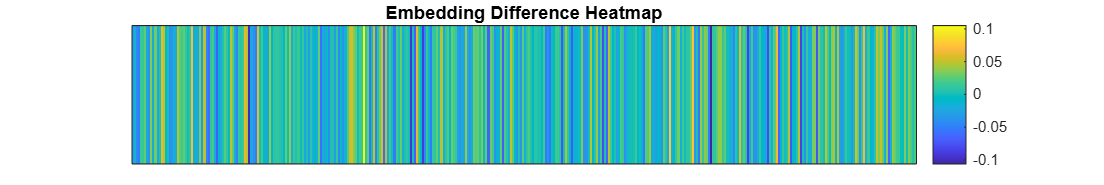

plotDifferenceEmbeddings(emb1,emb2)

Process the whole paragraph in one call

embeddings = model.encode(py.list(cellstr(sentences)'))
embeddings.shape

embeddings =   Python ndarray:

   -0.0452    0.0717    0.0172   -0.0317    0.0477   -0.0080    0.0122    0.0578   -0.0235    0.0005   -0.0059    0.1645    0.0872    0.0576   -0.0097    0.0257    0.0318    0.0049   -0.0225   -0.0381   -0.0568   -0.0270    0.0123    0.0493    0.0092    0.0301    0.0072    0.0636   -0.0289    0.0343   -0.0390   -0.0201    0.0009    0.0116   -0.0567    0.0033    0.0108   -0.0677    0.0246   -0.0008    0.0038   -0.0342   -0.0243   -0.0844    0.0169    0.0033    0.0806   -0.0887    0.0559    0.0244    0.0477   -0.0114    0.0462   -0.0806    0.0774    0.0492    0.0203   -0.0239    0.0524   -0.0098   -0.0552    0.0314   -0.0333    0.0791    0.0285   -0.0283   -0.0384    0.0542   -0.0150    0.1183   -0.0650    0.0174   -0.0081   -0.0539    0.0166    0.0465    0.0081   -0.0310   -0.0453    0.0762    0.0454   -0.0561   -0.0078    0.0448   -0.0041   -0.0303    0.0292   -0.0523    0.0565  

### Utils

Function to visualize a single embedding as a heatmap

function plotSingleEmbedding(embedding)

ans =   Python tuple with values:

    (18, 384)

    Use string, double or cell function to convert to a MATLAB array.


    % Create a figure with a custom size (in pixels)
    figure('Position', [100, 100, 1200, 200]);

    % Display the data as a heatmap
    imagesc(embedding);
    
    % Set a colormap 
    colormap("parula");
    
    % Remove y-axis ticks
    set(gca, 'YTick', []);
    
    % Add a colorbar to the side of the heatmap
    colorbar;
    
    % Set the title of the plot
    title('Single Embedding Heatmap');
end

Function to plot embeddings aligned

function plotAlignedEmbeddings(embedding1, embedding2)
    % Stack the embeddings for aligned visualization 
    % (each embedding is assumed to be a row vector)
    aligned_embeddings = [embedding1; embedding2];
    
    % Create a figure with a custom size (in pixels)
    figure('Position', [100, 100, 1200, 200]);

    % Display the data as a heatmap
    imagesc(aligned_embeddings);
    
    % Set colormap
    colormap("parula");
    
    % Set the y-axis ticks to correspond to the two embeddings
    set(gca, 'YTick', [1, 2], 'YTickLabel', {'Embedding 1', 'Embedding 2'});
    
    % Remove x-axis ticks
    set(gca, 'XTick', []);
    
    % Add a colorbar to the side of the heatmap
    colorbar;
    
    % Set the title of the plot
    title('Aligned Embeddings Heatmap');
end

Function to compare one embedding over another

function plotDifferenceEmbeddings(embedding1, embedding2)
    % Compute the difference between the embeddings
    difference = embedding1 - embedding2;
    
    % Create a figure with a custom size (in pixels)
    figure('Position', [100, 100, 1200, 200]);

    % Display the data as a heatmap
    imagesc(difference);
    
    % Set colormap 
    colormap(parula);
    
    % Remove x-axis and y-axis ticks for cleaner visualization
    set(gca, 'XTick', []);
    set(gca, 'YTick', []);
    
    % Add a colorbar to the side of the heatmap
    colorbar;
    
    % Set the title of the plot
    title('Embedding Difference Heatmap');
end